### Using MATLAB for data manipulationand analysis

#### An example of MATLAB array arithmetic

- Plot results

- programming logic

- array manipulations

- for loops

- Strategies for using for loops

Example of array arithmetic

Equation for bound reeptor as function of [ligand]

[L] + [R] <-> [LR]

k+, k-

[LR] = Rtotal * [L]/ (Kd+[L]), Kd = k-/k+, Rtotal is total amount of receptor

We want to plot [LR] versus [L] for range of different Kd

example: Rtotal = 20 nM

[L] varis from 0 - 200 uM

Kd can be 10, 30, 50, 70, 90 uM

Plot these on MATLAB

#### We are going to write 4 versions, from stupid to safisticated

## Plot LR version 1

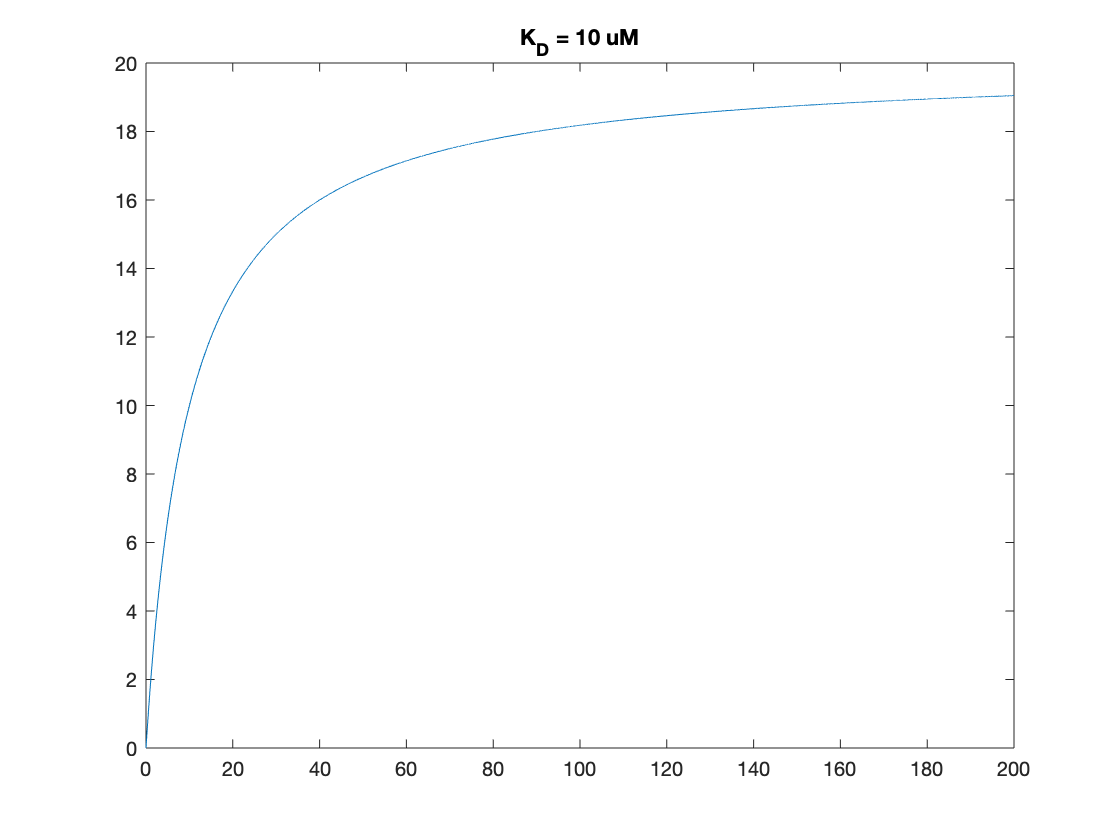

L = 0:0.01:200; % from 0 - 200, with step of 0.01
Rtot = 20;

KD = 10;
LR = Rtot*L./(L + KD); % use ./ to make element by element division
figure % make a figure
plot(L, LR) % L in x axis, LR in y axis
title('K_D = 10 uM') % write K_D then D is subscripted **

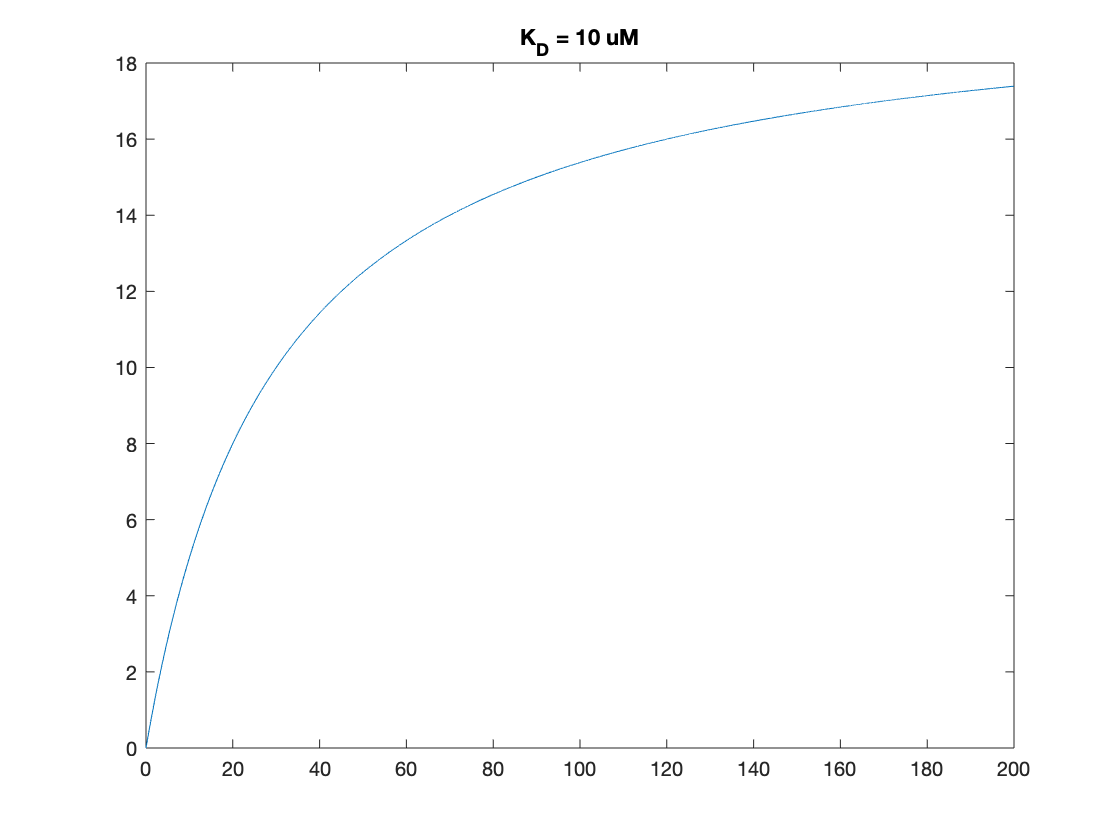

KD = 30;
LR = Rtot*L./(L + KD); % use ./ to make element by element division
figure % make a figure
plot(L, LR) % L in x axis, LR in y axis
title('K_D = 10 uM') % write K_D then D is subscripted

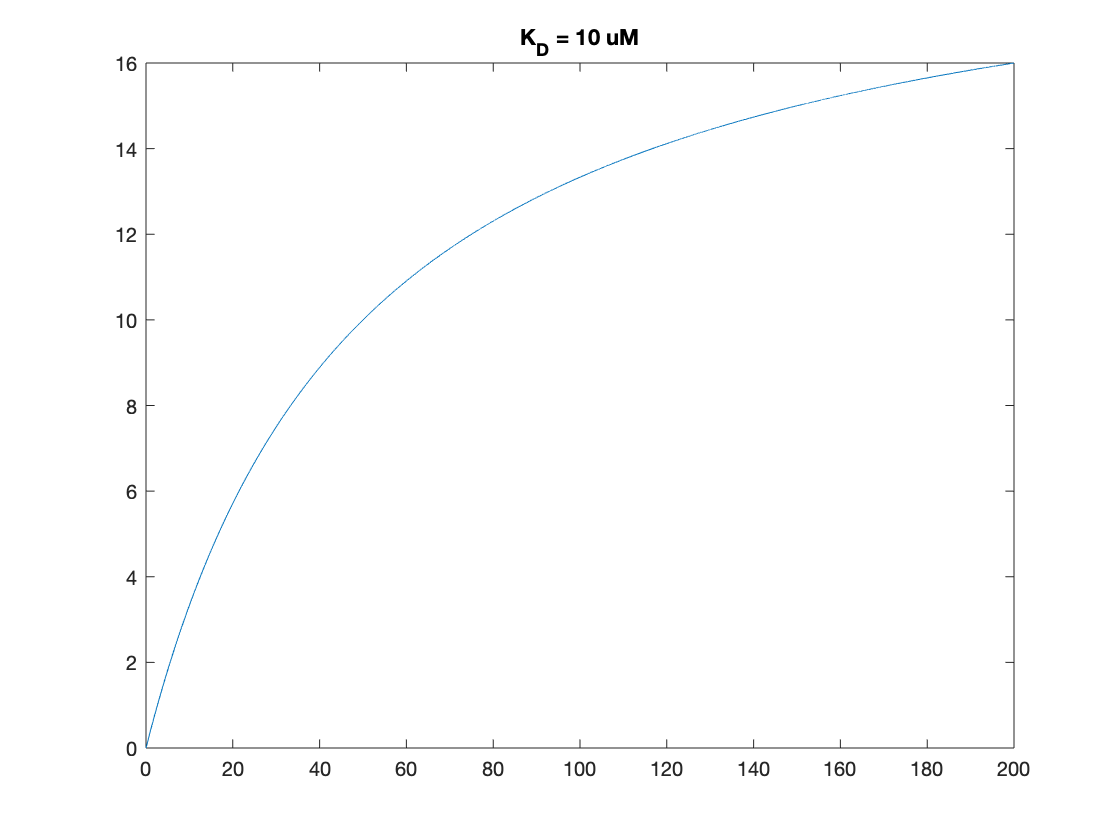


KD = 50;
LR = Rtot*L./(L + KD); % use ./ to make element by element division
figure % make a figure
plot(L, LR) % L in x axis, LR in y axis
title('K_D = 10 uM') % write K_D then D is subscripted

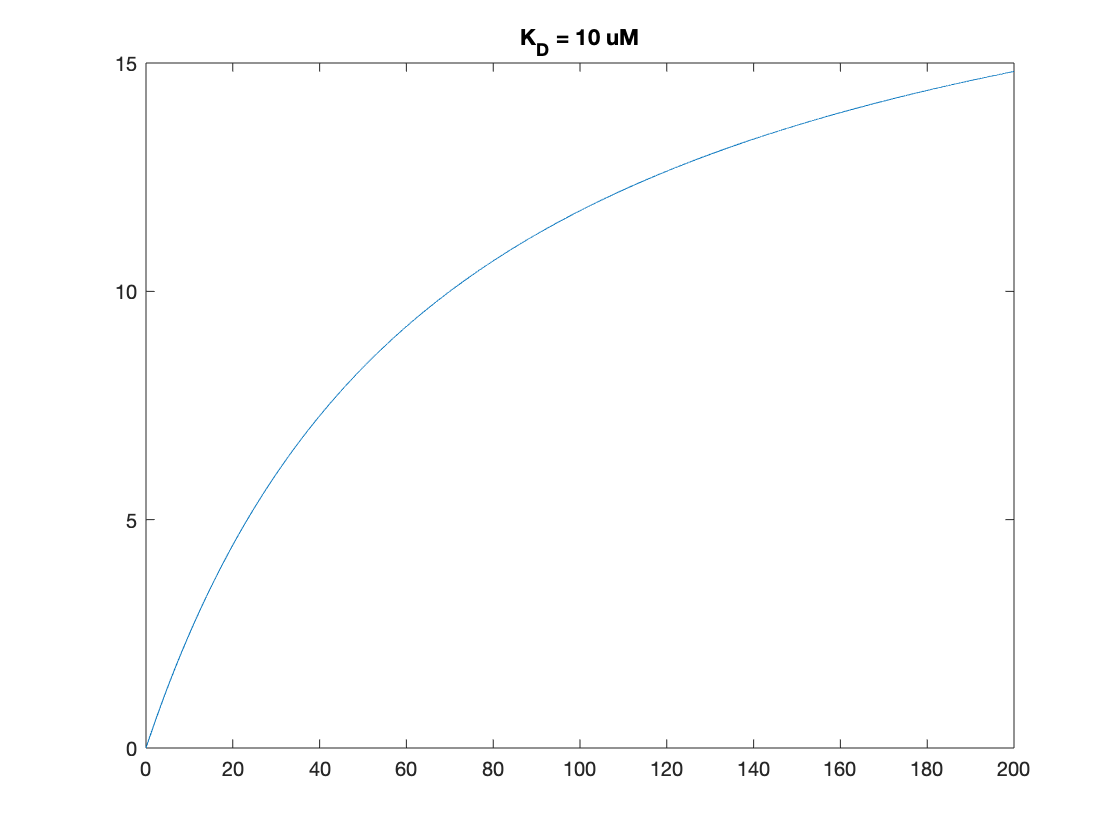

KD = 70;
LR = Rtot*L./(L + KD); % use ./ to make element by element division
figure % make a figure
plot(L, LR) % L in x axis, LR in y axis
title('K_D = 10 uM') % write K_D then D is subscripted

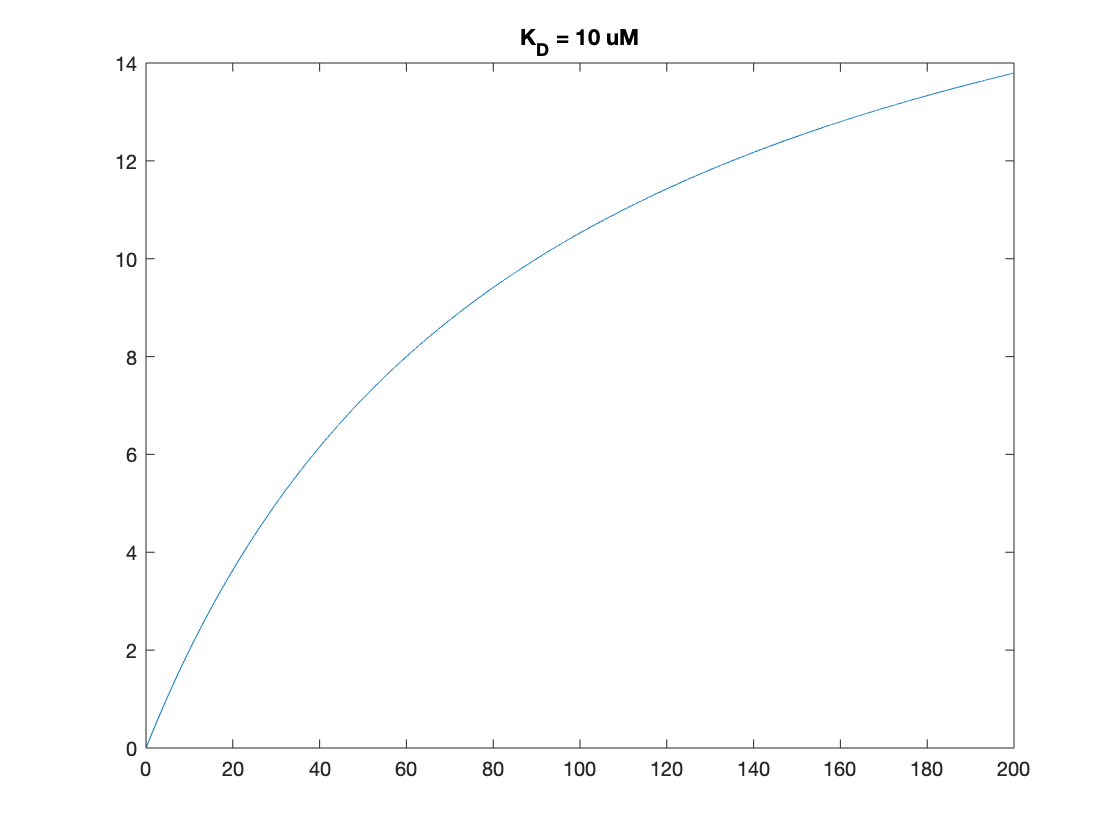


KD = 90;
LR = Rtot*L./(L + KD); % use ./ to make element by element division
figure % make a figure
plot(L, LR) % L in x axis, LR in y axis
title('K_D = 10 uM') % write K_D then D is subscripted

#### Version 1 is not ideal

Since they are in separate plots, and there is no labels

#### Version 2

colors = repmat('krgbmc',1,300) % repmat means repeat matrix, 'krgbmc' means black, red, green,blue, magenta, cyan; If it turns out to be

colors = 'krgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmckrgbmc

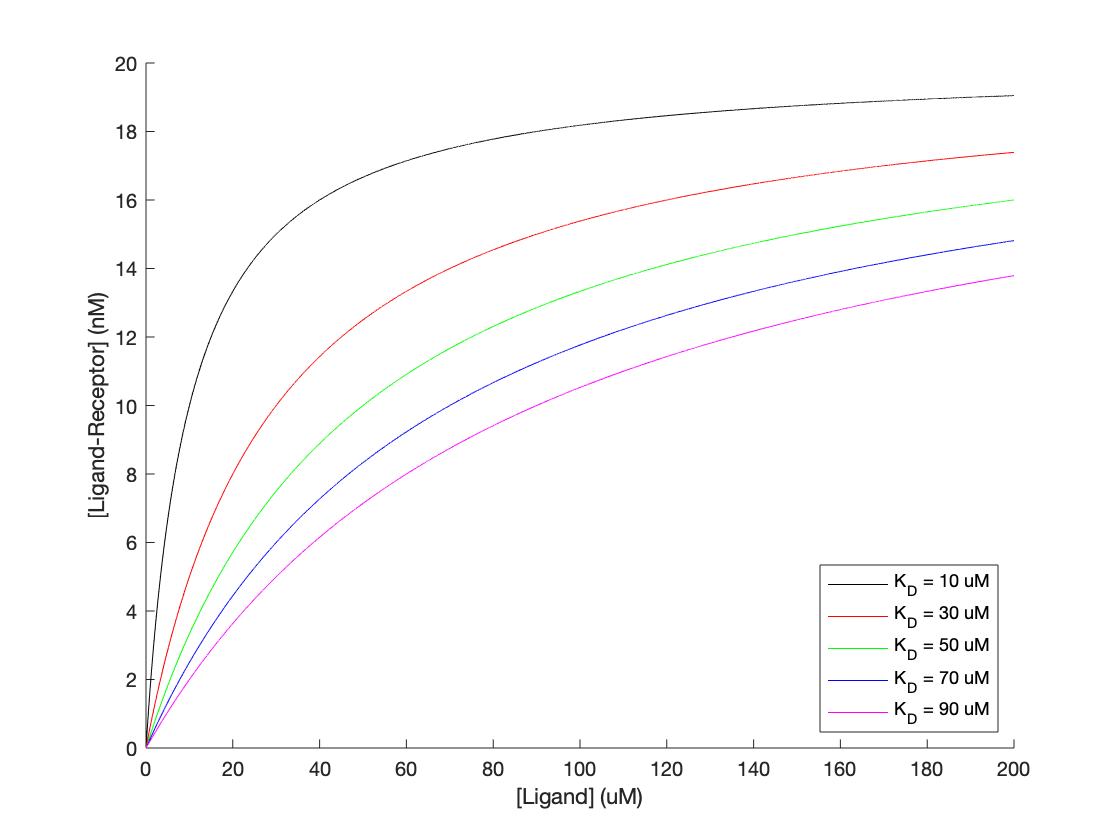

% more than 6 plots, then the color will repeat.
% 1 means from 1 to 300; 300 means repeat 300 times, it is arbiturily setted. 

L = 0:0.01:200;
Rtot = 20;

figure
hold on % plot onto 1 graph: key thing is to use hold on

KD = 10;
LR = Rtot*L./(L + KD);
plot(L,LR,colors(1))

KD = 30;
LR = Rtot*L./(L + KD);
plot(L,LR,colors(2))

KD = 50;
LR = Rtot*L./(L + KD);
plot(L,LR,colors(3))

KD = 70;
LR = Rtot*L./(L + KD);
plot(L,LR,colors(4))

KD = 90;
LR = Rtot*L./(L + KD);
plot(L,LR,colors(5))
xlabel('[Ligand] (uM)')
ylabel('[Ligand-Receptor] (nM)')
legend('K_D = 10 uM', 'K_D = 30 uM',...
    'K_D = 50 uM','K_D = 70 uM',...
    'K_D = 90 uM',...
    'Location','SouthEast') %... means when there is too long command, use ... to continue this same command in the next line.

### Version 3

Avoid repeat programming, what if we want to plot 500 conditions?

Use for loop

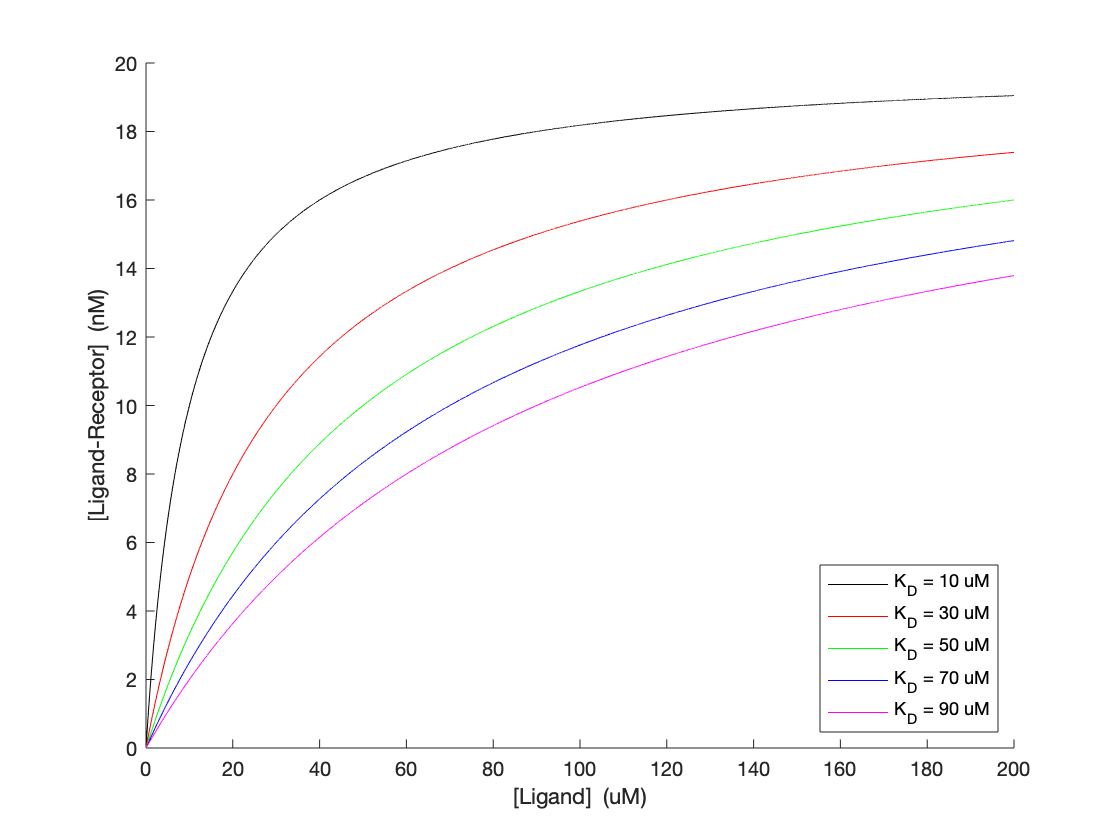

colors = repmat('krgbmc',1,300);
Rtot = 20;
L = 0:0.01:200;
KDs = 10:20:90; % define KDs to be a series of KD, with step size of 20, from 10 to 90.

figure
hold on

for i=1:5 % for loop, start value from 1 to 5
    KD = KDs(i);
    LR = Rtot*L./(L + KD);
    plot(L, LR, colors(i));
    figurelegend{i} = ['K_D = ', int2str(KD),' uM']; % int2str(KD) means from integer to string
    % ; note here is {}, cell array, special object
end

%
%a = 1:3

% a =

  %   1     2     3

% b = [5,3,2,8;2,1,9,23]

% b =

  %   5     3     2     8
  %   2     1     9    23

%c = [a,b]
%Error using horzcat
% Dimensions of arrays being concatenated are not consistent.
 
% should use cell array object
%c{1} = a;
%c{2} =b'

%c =

 % 1×2 cell array

 %   {1×3 double}    {4×2 double}

%c

%c =

%  1×2 cell array

%     {1×3 double}    {4×2 double}
% 
% c{3} = 'string variable'
% 
% c =
% 
%   1×3 cell array
% 
%     {1×3 double}    {4×2 double}    {'string variable'}
xlabel('[Ligand]  (uM)')
ylabel('[Ligand-Receptor]  (nM)')
legend(figurelegend, 'Location', 'SouthEast')

Version 3 problems:

- in the for loop , whatever we have calculated, it will be gone.

- if we want to have more KDs, we need to change for i = 1: *

### Version 4

colors = repmat('krgbmc', 1, 300);

Rtot = 20;
L = 0:0.01:200;
KDs = 10:20:90;

figure 
hold on

for i=1:length(KDs) % can increase KDs as however large the KDs is.
    KD = KDs(i);
    LR = Rtot*L./(L + KD);
    plot(L,LR,colors(i));
    LR_all(i,:) = LR; % store 1st row as LR, then 2nd row as LR;
    % look at the Workspace and find that the LR_all is a 5*20001 doouble
    % 5 rows of LR, the 1st is when KD=10, the 2nd row is when KD=30
    % etc.Now we can track back some specific points since all values are
    % stored.
    figurelegend{i} = ['K_D = ', int2str(KD), ' uM'];
end

xlabel('[Ligand]  (uM)')
ylabel('[Ligand-Receptor]  (nM)')
legend(figurelegend, 'Location', 'SouthEast')

MATLAB Principles illustrated by this example:

- Plotting: plot colors, figure, hold on, legend, xlabel, ylabel

- Array arithmetic: LR = L*Rtot./(L + KD)  (There are many values of L, from 0 to 200, so L is a vector. We need a element to element division - this is array arithmetic.

- Programming logic: command line VS. copu-paste vs. script

- Programming logic: for loops

- Array manipulations: access one row, LR_all(i,:) = LR

#### for loops

Used to repeat certain calculations several times

#### Typical generic structure

for (variable) = (sequence of numbers)

    (MATLAB commands to be repeated)

end

#### Example:

for i = 1:5

    output = 4*i^2 + 13

end

% This will calculate and display 5 values of the variable output according to the formula

#### Notes/hints on using for loops

All commands between for and end will be repeated

Each time through the loop, the 'index variable' will be different

This can be exploited to make each trip through the loop slightly different

Example 1: 

for i = 1:5

    parameter = 2*i;

end

Since i is different, you can exploit this to make something else to be different based on i, such as the parameter here.

Example 2:

values_to_test = [1, 13, 22, 300];  % if the sequence is not 1,2 etc but discontinuous numbers, you can put this sequence into a % varialbe, and index it by length and i

for i+1: length(valeus_to_test)

    parameter = values_to_test(i);

end

% specify A(:,i) tells MATLAB to plot a different column each trip through
% the loop.
% specify colors(i) tells MATLAB to plot each column in a different color.

